# Indoor Navigations App

## INIT


clear all;
close all;
clc
imaqreset

## Data Aquisition (i)


colorDevice = imaq.VideoDevice('kinect',1);
depthDevice = imaq.VideoDevice('kinect',2);

step(colorDevice);

ans =   ToolboxPreferencesManager with properties:

    GetPrefListener: [1×1 handle.listener]
    SetPrefListener: [1×1 handle.listener]


step(depthDevice);

colorImage = step(colorDevice);
depthImage = step(depthDevice);
% Bild von Kinect streamen (1 Frame)
ptCloud = pcfromkinect(depthDevice,depthImage,colorImage);

% Fuer mehrere Frames Player verwenden
% player = pcplayer(ptCloud.XLimits,ptCloud.YLimits,ptCloud.ZLimits,...
% 	'VerticalAxis','y','VerticalAxisDir','down');
% 
% xlabel(player.Axes,'X (m)');
% ylabel(player.Axes,'Y (m)');
% zlabel(player.Axes,'Z (m)');
% 
% for i = 1:50
%    colorImage = step(colorDevice);  
%    depthImage = step(depthDevice);
%  
%    ptCloud = pcfromkinect(depthDevice,depthImage,colorImage);

%    view(player,ptCloud);
% end

% Kamera Objekt wieder freigeben
release(colorDevice);
release(depthDevice);
%Pointcloud als ACSII PLY Datei abspeichern
pcwrite(ptCloud, 'scene.ply','Encoding','ascii');


## Pointcloud einlesen und bearbeiten

pc = pcread('scene.ply');
square = 0.1;
roi = zeros(1,3);
index = 1;
% Alle Punkte in der Pointcloud abspeichern und 1m^2 grosse ROI speichern
tic
for i = 1:pc.Count
   point(i,:) = pc.Location(i,:);
   if (point(i,2) >= (-square) && point(i,2) <= square) && (point(i,1) >= (-square) && point(i,1) <= square)
       roi(index,:) = pc.Location(i,:);
       index = index + 1;
   end
end
toc
% ROI als .mat abspeichern mit Zeitstempel
data = struct('time', datestr(now), 'roi', roi);
save('data.mat', 'data');

## Plots

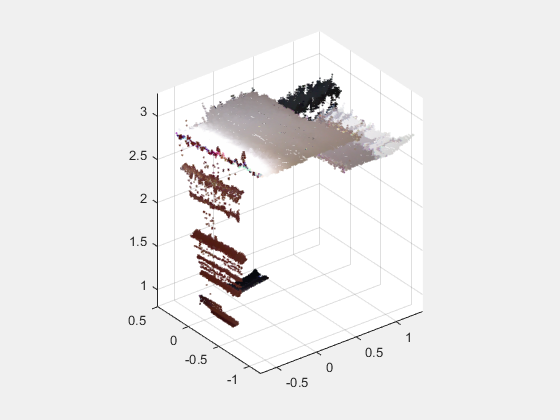

% Pointcloud anzeigen
load('data.mat')
pcshow(pc);

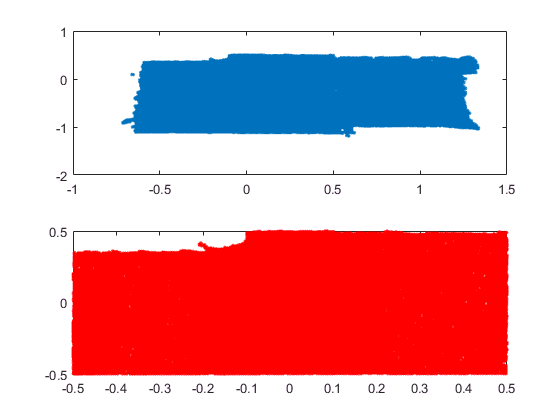

% Profillinie
figure
subplot(2,1,1)
plot(point(:,1), point(:,2),'.')
subplot(2,1,2)
plot(data.roi(:,1), data.roi(:,2),'.r')